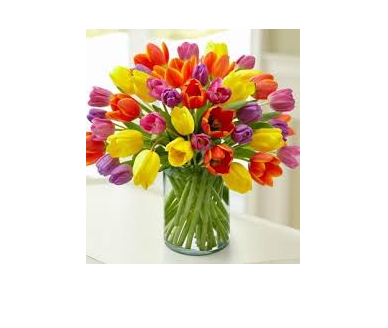

he = imread('images (2).jpg');
imshow(he)

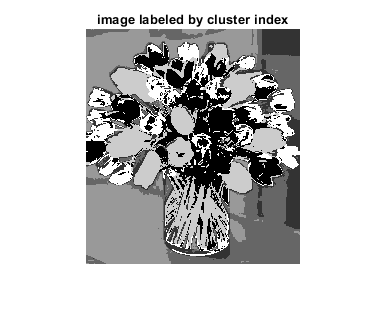

R = he(:,:,1);
G = he(:,:,2);
B = he(:,:,3);

he=im2double(he);
ab = he(:,:,2:3);
nrows = size(ab,1);
ncols = size(ab,2);
ab = reshape(ab,nrows*ncols,2);

nColors = 6;
% repeat the clustering 3 times to avoid local minima
[cluster_idx, cluster_center] = kmeans(ab,nColors);

pixel_labels = reshape(cluster_idx,nrows,ncols);
imshow(pixel_labels,[]), title('image labeled by cluster index');

segmented_images = cell(1,3);
rgb_label = repmat(pixel_labels,[1 1 3]);

for k = 1:nColors
    color = he;
    color(rgb_label ~= k) = 0;
    segmented_images{k} = color;
    color
    
end

color = color(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

color = color(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

color = color(:,:,1) =

    0.9490    0.9529    0.9529    0.9569    0.9608         0    0.9647         0    0.9647    0.9608    0.9569    0.9451    0.9333    0.9255    0.9176    0.9137    0.9098    0.9137    0.9176    0.9216    0.9255    0.9294    0.9333    0.9373    0.9412    0.9412    0.9412    0.9412    0.9412    0.9412    0.9412    0.9412    0.8902    0.8902    0.8902    0.8863    0.8824    0.8784    0.8784    0.8745    0.8627    0.8706    0.8863    0.9020         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.9098    0.8824    0.8824    0.8863    0.8902    0.8941    0.8980    0.8980    0.8980         0         0    0.9255    0.9255    0.9373    0.9373    0.9451    0.9373    0.9333    0.9294    0.9255    0.9216    0.9216    0.9176    0.9176    0.9137    0.9020    0.9059    0.9098    0.9137    0.9216    0.9294    0.9333    0.9373         0      

color = color(:,:,1) =

         0         0         0         0         0    0.9647         0    0.9686         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.9176    0.9255    0.9333    0.9294    0.9176    0.9098    0.9176    0.9216    0.9294    0.9294    0.9451    0.9451    0.9569    0.9529    0.9490    0.9412    0.9294    0.9216    0.9176         0         0         0         0         0         0         0         0         0    0.9176    0.9176         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.9647    0.

color = color(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

color = color(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

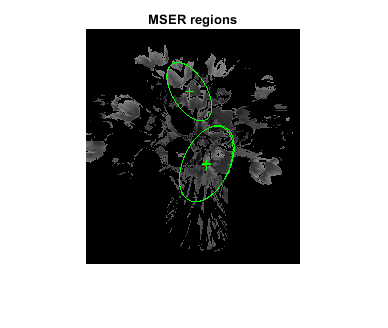


%imshow(segmented_images{1}), title('objects in cluster 1');
% Detect MSER regions.
I = rgb2gray(segmented_images{1});
[mserRegions, mserConnComp] = detectMSERFeatures(I,'RegionAreaRange',[1000 2000],'ThresholdDelta',1);

figure
imshow(I)
hold on
plot(mserRegions, 'showPixelList', false,'showEllipses',true)
title('MSER regions')
hold off

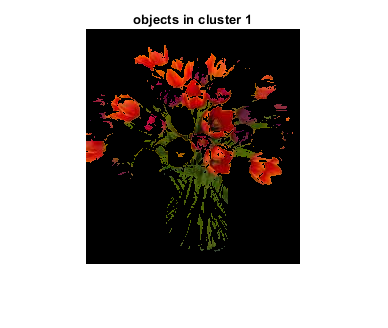


imshow(segmented_images{1}), title('objects in cluster 1');

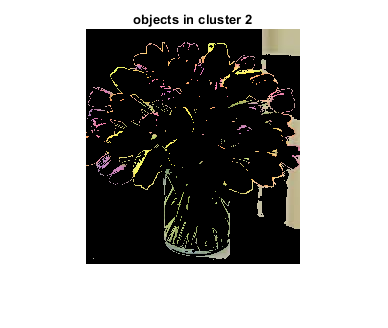


imshow(segmented_images{2}), title('objects in cluster 2');

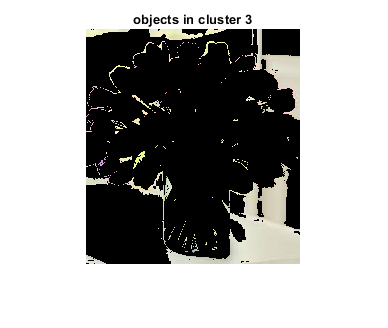


imshow(segmented_images{3}), title('objects in cluster 3');

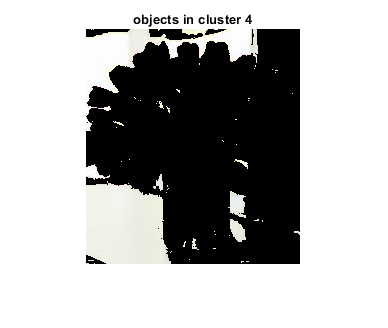


imshow(segmented_images{4}), title('objects in cluster 4');

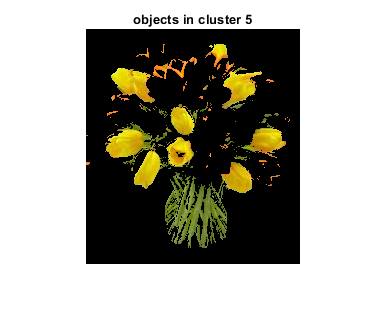



imshow(segmented_images{5}), title('objects in cluster 5');

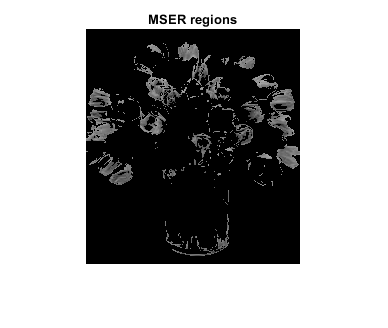


%imshow(segmented_images{6}), title('objects in cluster 6');

I = rgb2gray(segmented_images{6});
[mserRegions, mserConnComp] = detectMSERFeatures(I,'RegionAreaRange',[1000 2000],'ThresholdDelta',1);

%mserRegions.
figure
imshow(I)
hold on
plot(mserRegions, 'showPixelList', false,'showEllipses',true)
title('MSER regions')
hold off